# Integrated ORP-HEFA Model (Single County)

This live script is used to run the integrated microalgae model. The modules within the integrated model include:

- **Thermal Model:** Determines pond temperatures and evaporation with hourly resolution in the location of interest

- **Growth Model: **Determines the microalgae growth rate with hourly resolution in the location of interest

- **Cultivation and Dewatering Model:** Determines energy consumption for pumps and paddlewheels, consumption of ammonia, DAP, and CO2, blue and green water footprint, and the net biomass output from cultivation in Open Raceway Ponds (ORPs) with a 3-stage dewatering process (bioflocculation, membrane separation, and centrifugation)

- **Storage Model:** Determines additional requirements for long-term (6+ months) anaerobic biomass storage to offset seasonal production variability, storage losses, and the resulting biomass composition sent to fuel conversion

- **Lipid Extraction Model: **Determines the hexane solvent, electric energy, and thermal energy requirements for high-pressure homogenization (HPH) and the Wet Hexane Extraction (WHE) steps required for lipid extraction and sizes all required equipment.

- **Hydroprocessed Esters and Fatty Acids (HEFA) Model: **Determines the chemicals, catalysts, electric energy, and thermal energy requirements for the HEFA process. The module sizes the refinery equipment required for hydrotreating, isomerization, gas processing, onsite steam-methane reforming (SMR) for hydrogen production and auxiliary equipment including the cooling water tower and pump and a tank farm for short term storage of liquid and gaseous fuels. The HEFA model also determines the hourly output of propane, LNG, naphtha, diesel, and jet fuel. 

- **Anaerobic Digestion Model: **Determines the electric and thermal energy requirements for anaerobic digestion of lipid extracted algae (LEA) for the recovery of nutrients and energy. The digested LEA forms biogas which is cleaned up with the Pressure Swing Absorption (PSA) process and sent to a Combined Heat and Power (CHP) plant. Electric energy is used on-site with excess being sold to the grid. Thermal energy is used on-site with excess considered a zero-value zero-burden waste product. Nutrients recovered in the aqueous supernatant are recycled to algae ponds and solid Nitrogen and Phosphorus in the digestate are land applied to avoid emissions and costs associated with landfilling. 

- **Techno-Economic Analysis (TEA): **Determines the total capital expenditure and annual operational expenses for the integrated biorefinery and solves for the minimum product selling prices (MPSP) for biomass, lipids, jet/diesel fuel, and the contribution to the MPSP from the conversion process only using a 30-year discounted cash flow rate of return (DCFROR) analysis with standard Nth-plant economic assumptions

- **Life Cycle Assessment (LCA):** Determines the life cycle environmental impacts of the integrated biorefinery across all 10 impact categories from the Tool for the Reduction and Assessment of Chemical and other environmental Impacts (TRACI 2.1), and total freshwater consumption 

## Step 1: Define Inputs for the Process Model

While some of the model inputs are adjustable by the user, many inputs are built into the model to increase ease-of-use and ensure accurate reporting. The adjustable inputs are defined by the use below:

### 1.1 Facility Location:

Select the State and County and whether to include rainfall for the simulation using the dropdown menus. 

clear 
clc
load background_data.mat county_dat
states_val = unique(county_dat(:,4));

State = states_val(10);
states_indx = find(strcmp(county_dat(:,4),State));
county_val = unique(county_dat(states_indx,3)); 

try
County = county_val(2);
catch
County = county_val(1);
end

% Weather file path
[file_ids,weather_script,coords] = weather_finder(County,State);

% Parse weather
T_amb= (weather_script(:,4)); % ambient temperature deg C
RH= weather_script(:,5); % relative humidity (%)
WNDSPD= weather_script(:,3); % wind speed (m per sec)
GHI= weather_script(:,2); % GHI (W per m2) 

Rainfall = "Off";  %option for rainfall turned off for open source model
    if Rainfall == "On"
    rainfall_mat = weather_script(:,6)/1000; % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 

Value = [County; max(weather_script(:,1)); mean(T_amb); mean(RH); (sum(GHI)/max(weather_script(:,1)))/1000; (sum(rainfall_mat)/max(weather_script(:,1)))*100/2.54];
fprintf('Average Weather Parameters for %s County (Average of %.0f Weather Stations)  \nAverage Ambient Temperature = %.1f degrees C \nAverage Relative Humidity = %.0f%% \nTotal Annual Global Horizontal Irradiance (GHI) = %.1f kWh/m2 \nTotal Annual Rainfall = %.1f inches \n', Value); 

Average Weather Parameters for Honolulu County (Average of 13 Weather Stations)  
Average Ambient Temperature = 24.9 degrees C 
Average Relative Humidity = 79% 
Total Annual Global Horizontal Irradiance (GHI) = 1941.0 kWh/m2 
Total Annual Rainfall = 0.0 inches 


### 1.2 Facility Size and Layout:

Select the facility size in total wetted-acres and specify the size of individual ponds. Expect the MBSP and MFSP to increase significantly with facility sizes smaller than 5000 wetted-acres due to economies of scale.

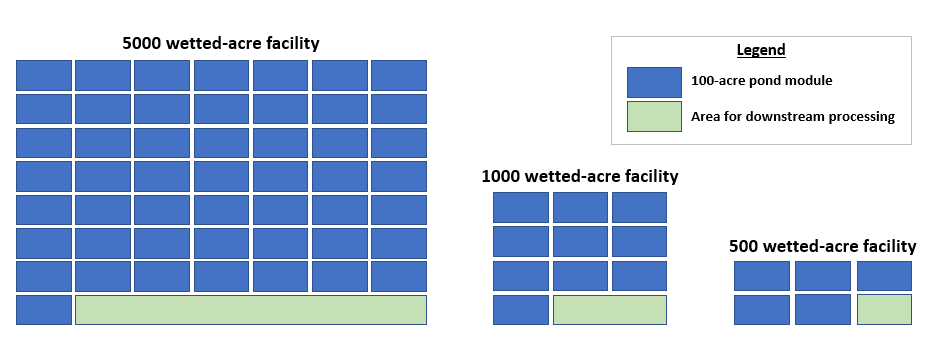

wetted_acres = 5000; % wetted-acres
pond_size = 10; % acres
depth = 0.2; % m
max_depth = 0.25*100; % enter in m, converted to cm
min_depth = 0.15*100; % enter in m, converted to cm

*"Max Pond Depth" must be greater than "Pond Depth" and "Min Pond Depth" must be less than "Pond Depth" specified above.*

% Facility Size and Layout 
num_ponds = ceil(wetted_acres/pond_size);
module_size = 100; % wetted-acres (fixed)
    if pond_size == 10
        if wetted_acres == 5000
            length_orp = 2*670*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 2*670*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    else 
        if wetted_acres == 5000
            length_orp = 4*417*7; % m --> module is 2 ponds wide (670 m length per pond); Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        else 
            length_orp = 4*417*3; % m --> total length for 5000 wetted acres with 10-acre ponds is 10070.4 m in Davis et al., 2016
            width = wetted_acres*4047/length_orp; % determine width to achieve total wetted acres
        end 
    end 

% Define Geometry Vector as Model Input 
geom_vec = [length_orp width depth max_depth min_depth] ;

### 1.3 Harvesting Sequence:

Define harvesting parameters for the cultivation facility including the pond inoculation concentration, the concentration at which harvesting is triggered, and maximum days between automated harvesting events (regardless of pond concentration). If "Rainfall" is turned on, harvesting is also triggered when rainfall causes the pond depth to exceed the maximum allowable depth specified above. *Please note the harvesting concentration must be greater than the inoculation concentration.*

% Harvest sequence, concentrations in gpL and days to harvest
CX_inoculation = 0.1*1000; % entered as gpL and converted to g/m3
CX_harvesting = 0.6*1000; % entered as gpL and converted to g/m3
harv_days = 5; % days until automated harvest cycle is triggered

%Build model input vectors
harvest_vec = [CX_inoculation CX_harvesting harv_days 250 4000]; %[initial_CX final_CX days_to_harvest i_salt salt_max_cx]

strain = "S_obliquus"; 
strain_vec =[305.4, 276.2, 314.1, 0.38, 480, 0.03, 1.5]; %[max temp, min temp, optimal temp, ODC, sat light intensity, dark respiration losses, phi] - phi is photon efficiency of 12 g biomass/8 mol photons = 1.5

### 1.4 Nutrients and CO2 Consumption Parameters:

Define the C, N, and P content of the microalgae to quantify the consumption of ammonia, DAP, and CO2 used for cultivation. *Please enter percentages in decimal form (for example, 25% is         entered as 0.25).*

**    Carbon Content and Carbon Utilization Efficiency:**

c_content = 0.54; % ash-free dry weight basis 
sparge_eff =  0.95; %Carbon utilization efficiency (CUE)

%Optional inputs to include CO2 capture energy and emissions in boundary
CO2_capture_elec_en = 0; %MJ elec/tCO2 captured supplied by local grid
CO2_capture_therm_en = 0;  %MJ thermal/tCO2 captured supplied by NG - enter 0 and include emissions from thermal energy gen. in indirect emissions when using waste heat 
CO2_capture_indir_GHG = 0;  %GHG from CO2 capture consumables (MEA, water, other chemicals, sorbents, solvents, etc.) - will vary based on CO2 capture tech.

%Build model input vectors
co2_capt_lci = [CO2_capture_indir_GHG; CO2_capture_therm_en; CO2_capture_elec_en];

**    N + P Content in Algae and Nutrients:**

rep_dep = "Nutrient Replete";
p_content = 0.0022; % ash-free dry weight basis
n_content = 0.018; % ash-free dry weight basis
p_content_dap = 0.2; % dw basis
n_content_dap = 0.18; % dw basis
n_content_ammonia = 0.82; % dw basis

    switch rep_dep
        case 'Nutrient Replete'
        nutrient_surpluss = 0.2; % percentage surplus of nutrients supplied
        case 'Nutrient Deplete'
        nutrient_surpluss = 0.0; % percentage surplus of nutrients supplied 
    end 

**    Transportation distances for Ammonia:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
ammonia_transp_lorry = 148;
ammonia_transp_train = 276;
ammonia_transp_inland_ww = 47;
ammonia_transp_sea_container = 841;

**    Transportation Distances for DAP:**

% Ecoinvent default: 276 km by freight train, 47 km by freight-inland waterways, 148 km  by freigh lorry-unspecified, 
% 841 km by sea container ship - transportation distances in km
DAP_transp_lorry = 148;
DAP_transp_train = 276;
DAP_transp_inland_ww = 47;
DAP_transp_sea_container = 841;

%Build model input vectors
transp_vec = [ammonia_transp_train, ammonia_transp_inland_ww, ammonia_transp_lorry, ammonia_transp_sea_container; % ammonia
              DAP_transp_train, DAP_transp_inland_ww, DAP_transp_lorry, DAP_transp_sea_container]; % DAP

### 1.5 Inputs for Anaerobic Storage:

    **Microalgae Composition (dry weight basis):**

*    Please note the algae composition must sum to 100% (proteins + carbohydrates + lipids + ash = 100%). Enter percentages in decimal form. *

prot = 0.09; % dry wt%
carb = 0.421; % dry wt%
lip = 0.412; % dry wt%
ash = 0.077; % dry wt%

sum_comp = (prot + carb + lip + ash)*100;
fprintf('Current Sum = %0.2f %%', sum_comp);

Current Sum = 100.00 %

**    Anaerobic Storage Parameters:**

degradation = 0.05; % dry matter lost to acid formation - based on Wendt et al., 2019 (INL)
centr_out_dens = 1042; %kg/m3 - Li et al., 2020
pump_eff = 0.7; % pumping efficiency

% Build model input vector - comp_vector
comp_vector = [c_content sparge_eff p_content p_content_dap n_content_dap n_content n_content_ammonia nutrient_surpluss ash];

### 1.6 Inputs for Lipid Extraction Model:

    **Lipid Extraction System Boundary and Operational Days:**

LE_inc_AD_CHP = "Yes";
annual_uptime = 330; 

%Calculate annual operational hours based on operational days
op_hours = annual_uptime*24;

    **High-Pressure Homogenization:**

HPH_num_passes = 2; % Tetraselmis = 1 (low pressure); Chlorella = 2 (high pressure); Nanno = 6 (high pressure) 
HPH_pressure = 400;   % high pressure = 1500 bar; low pressure = 400 bar
    if HPH_pressure == 1500
    HPH_flowrate = 5; % m3/hr per unit
    else 
    HPH_flowrate = 23; % m3hr per unit 
    end 

    **Wet Hexane Extraction (WHE):**

WHE_thermal_en = 1.7; % 1.7 kWh_thermal/kg oil
WHE_electric_en = 0.54; % 0.54 kWh_elec/kg oil
WHE_solvent_to_biomass = 1.8; % 1.8 g hexane/g wet biomass
WHE_hexane_loss = 5.2; % 5.2 g hexane/kg oil
WHE_extraction_eff = 100/100; % 95 percent of lipids extracted

%Build model input vector
WHE_model_inputs = [WHE_thermal_en; WHE_electric_en; WHE_solvent_to_biomass; WHE_hexane_loss; WHE_extraction_eff];

### 1.7 Inputs for Hydroprocessed Esters and Fatty Acids (HEFA) Model:

    **HEFA Process Options (Fuel Profile and H2 Production):**

HEFA_scenario = "Maximum Jet"; % Maximum Jet or Maximum Distillate
HEFA_H2_scenario = "Purchased"; % Purchsed or Onsite SMR
HEFA_CO2_recycle = "No"; % Recycle CO2 to pond? Yes//No
ng_boiler_eff = 0.8; % Natural gas boiler efficiency (80% default)

### 1.8 Inputs for the Techno-Economic Analysis

Use this section to define commodity prices such as ammonia, DAP, electricity, and CO2 and to define critical assumptions for the cash flow analysis.

    **Assumptions for the Discounted Cash Flow Rate of Return Model:**

Cost_year = 2019; % cost year used to adjust CAPEX and OPEX
IRR = 0.1; % Internal Rate of Return in DCFROR 

    **Commodity Prices and Transportation Distances:**

*    Default commodity prices are reported in 2019 dollars. Enter commodity prices in 2019 dollars and all costs are indexed within the model to the "Cost Year" entered above.*

    Cultivation Consumables:

load background_data.mat

% Cost Indices and establishing project year
CAPEX_INDEX = table2array(CAPEX_CEPI_INDEX);
CHEM_INDEX = table2array(CHEMICAL_INDEX); 
ELEC_INDEX = table2array(ELEC_INDEX);
LABOR_INDEX = table2array(LABOR_INDEX);

CAP_IND_POS = Cost_year - 1989; 
CHEM_IND_POS = Cost_year - 1979; 
ELEC_IND_POS = Cost_year - 2013; 
LABOR_IND_POS = Cost_year - 1989; 

%Commodity prices
Elec_cost = 0.07*(ELEC_INDEX(ELEC_IND_POS,2)/ELEC_INDEX(6,2)); % 2019$/kWh - EIA (2019)
CO2_cost =50; % $/tCO2
ammonia_cost = 0.8; % $/kg in 2019 USD (from $0.39/lb in 2011 dollars - Davis et al.)
dap_cost = 0.66; % $/kg in 2019 USD (from $0.32/lb in 2011 dollars - Davis et al.)

    Lipid Extraction and HEFA Consumables:

%Commodity prices - all prices indexed to project year using 
NG_cost = 0.2154*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(40,2)); % 2011$/kg - $5.10/1000 scf - Dutta et al., 2011; indexed to 2019 dollars
H_cost = 1.47*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(40,2)); % 2012$/kg - Dilich et al., 2012; indexed to 2019 dollars
Process_water_cost = 0.204/1000*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(40,2)); % $/m3 converted to $/kg - 2011$/kg - Dutta et al., 2011; indexed to 2019 dollars
Hexane_cost = 0.71*(CHEM_INDEX(CHEM_IND_POS,2)/CHEM_INDEX(36,2)); % $/kg - assumption based on 2015 market price ($670-710/MT N Hexane) indexed to proj year
carbon_offset_cost = 45; % $45/tCO2 -assumption 
lip_purch_price = 0.75; % $0.75 per kg lipid for conversion only system boundary

% Critical Inputs Cost Matrix
cost_matrix = [Elec_cost, ammonia_cost, dap_cost, CO2_cost]; %$/kWh, $/kg ammonia, $/kg DAP, $/tCO2
SAF_consumables_costs = [Elec_cost; ammonia_cost; dap_cost; CO2_cost; NG_cost; 0; H_cost; Process_water_cost; Hexane_cost; carbon_offset_cost; lip_purch_price];

*    *For the "Conversion Only" system boundary please enter an oil/lipid (feedstock) purchasing price.*

    Fuel Product Values*:*

% Value of produced fuel products - https://afdc.energy.gov/fuels/prices.html
value_propane_gal = 3.55; 
value_LNG_gal = 3.63; % $/DGE (6.059 lbs of LNG per DGE)
value_naphtha_gal = 4.05; 
value_jet_gal = 2.46; 
value_diesel_gal = 5.17;
SAF_fuels_value_mat = [value_propane_gal; value_LNG_gal; value_naphtha_gal; value_jet_gal; value_diesel_gal];

    **DGE = Diesel Gallon Equivalents (6.059 lbs of LNG per DGE*

    *Fixed Operational Expenses Costing Model:*

fixed_opex_case = "Pearlson"; % Pearlson or Chen and Quinn

% SAF model dropdown menu inputs for model
SAF_dropdowns = [LE_inc_AD_CHP; HEFA_scenario; HEFA_H2_scenario; HEFA_CO2_recycle; fixed_opex_case];

## Step 2: Run the Model with the Current Inputs

 

%paramters used in optimization that are not used here
prod_scale = 1;
nut_rem = 0; 
rec_P = 0;
grid_red = 0; 

% Pre-allocate Variables
Cult_Out_Station_D = zeros(26, size(coords,1));
LE_proc_mod_out_D = zeros(20, size(coords,1)); 
SAF_proc_mod_out_D = zeros(29, size(coords,1)); 
pond_temps_mat = zeros(4, size(coords,1)); 
cult_TEA_out_CAPEX_D = zeros(61,size(coords,1)); 
cult_TEA_out_OPEX_D = zeros(9,size(coords,1));
LE_CAPEX_out_D = zeros(15,size(coords,1));
SAF_CAPEX_out_D = zeros(26, size(coords,1)); 
LE_OPEX_out_D = zeros(11,size(coords,1));
SAF_OPEX_out_D = zeros(16, size(coords,1)); 
storage_fcn_out_D = zeros(12, size(coords,1)); 
DCFROR_D = zeros(5, size(coords,1)); 
MBSP = zeros(size(coords,1),1); 
LE_coprod_mat_D = zeros(4, size(coords,1));
SAF_total_coprod_mat_D = zeros(8, size(coords,1));
SAF_LCA_consum_D = zeros(48, size(coords,1));
aware_cult_1_D = zeros(size(coords,1), 13); 
aware_cult_2_D = zeros(size(coords,1), 13); 

for i = 1:size(coords,1) 
    weather_input = weather_script(weather_script(:,1) == i, [4,5,2,3]);
    T_amb = weather_script(weather_script(:,1) == i, 4);
    RH = weather_script(weather_script(:,1) == i, 5);
    GHI = weather_script(weather_script(:,1) == i, 2);
    WNDSPD = weather_script(weather_script(:,1) == i, 3);
    
    if Rainfall == "On"
    rainfall_mat = weather_script(weather_script(:,1) == i, 6)/1000; % m per hr, hourly average
    else 
    rainfall_mat = zeros(8760,1);
    end 
    
    % Thermal model
    [TR,evap_rate, Water_con, M_Evap] = thermal_fcnV6(weather_input,geom_vec); 
    
    % Thermal model outputs
    annual_evap_cm_day = evap_rate(1,5);
    pond_temps_mat(:,i) = [max(TR)-273.15; min(TR)-273.15; mean(TR)-273.15; annual_evap_cm_day];
    
    % Cultivation and storage functions
    [CX, centr_out, centr_out_ann, cult_out, water_vol, CO2_demand_hourly,aquifer_hrly, area, total_recycled, num_settling_ponds, settlers_out, membrane_out,aware_cult, nutrients, recycled_membr_centr, dep_rep_scaling, harvest_water, Conc_at_Harvest, light_eff_track, aquifer, rec_algae, biomass_balance, energy_balance, dewatering_mat, check_biomass] = cultivation_fcn([TR GHI M_Evap rainfall_mat],geom_vec,strain_vec, harvest_vec, comp_vector, rep_dep, prod_scale, carb, lip, prot);
    [storage_fcn_out, ann_ave_centr, biomass_balance_st, comp_ann_ave_centr] = Storage_fcn(prot, carb, lip, ash, centr_out, centr_out_dens, degradation, pump_eff);
    
        % Protein extraction and value recovery
        if rec_P > 0
    
        protein_out_storage = biomass_balance_st(2,3); %kg protein per year
        protein_diverted = rec_P*protein_out_storage; %kg protein/yr diverted and recovered
        protein_value = 5; %dollars per kg protein product
        protein_revenue = protein_diverted*protein_value; % $5/kg per kg protein diverted and recovered as annual revenue
        
        ann_ave_centr = (ann_ave_centr*8760 - protein_diverted)/8760; %kg/hr - protein diverted (kg/hr)
        
        conv_feed_prot =  protein_out_storage*(1-rec_P); 
        conv_feed_carb = biomass_balance_st(3,3); 
        conv_feed_lip = biomass_balance_st(4,3); 
        conv_feed_ash = biomass_balance_st(5,3); 
        conv_feed_total = conv_feed_prot + conv_feed_carb + conv_feed_lip + conv_feed_ash; % kg DW/hr (includes ash)
        
        prot_n = conv_feed_prot/conv_feed_total; 
        carb_n = conv_feed_carb/conv_feed_total; 
        lip_n = conv_feed_lip/conv_feed_total; 
        ash_n = conv_feed_ash/conv_feed_total; 
    
        water_in = ann_ave_centr*8760*0.80; %total kg water in = water out
        AFDW_out = conv_feed_prot + conv_feed_carb + conv_feed_lip;
        ppe_TSS = AFDW_out/(AFDW_out + water_in); 
          
        %Mass balance for protein extraction
        biomass_balance_PE(1,1) = protein_diverted;
        biomass_balance_PE(2,1) = protein_diverted;
        biomass_balance_PE(3,1) = 0;
        biomass_balance_PE(4,1) = 0;
        biomass_balance_PE(5,1) = 0;
        
        biomass_balance_PE(1,2) = conv_feed_total;
        biomass_balance_PE(2,2) = conv_feed_prot;
        biomass_balance_PE(3,2) = conv_feed_carb;
        biomass_balance_PE(4,2) = conv_feed_lip;
        biomass_balance_PE(5,2) = conv_feed_ash;
    
        % Biomass mass balance between cultivation, dewatering, storage and protein extraction
        comp_biomass_balance = [biomass_balance biomass_balance_st biomass_balance_PE]; 
        
        % Outputs to conversion 
        algae_comp_to_con = [prot_n; carb_n; lip_n; ash_n; ppe_TSS]; 
        
        else 
        %Protein revenue is zero
        protein_revenue = 0; 

        % Biomass mass balance between cultivation, dewatering, storage
        comp_biomass_balance = [biomass_balance biomass_balance_st];
            
        % Composition and solids from storage - ps: post-storage
        ps_prot = str2double(storage_fcn_out(3,2));
        ps_carb = str2double(storage_fcn_out(4,2));
        ps_lip = str2double(storage_fcn_out(5,2));
        ps_ash = str2double(storage_fcn_out(6,2));
        ps_TSS = str2double(storage_fcn_out(12,2));
    
        % Outupts to conversion
        algae_comp_to_con = [ps_prot; ps_carb; ps_lip; ps_ash; ps_TSS];
    
        end

    % Areal Productivity Calcs at different stages
    areal_prod = str2double(cult_out(2,2)); %productivity calculated in cultivation function 
    areal_prod_adj = sum(centr_out)*0.20*1000/area/365; %productivity calculated using centr_out (after dewatering) - 20% solids is on an AFDW basis
    areal_prod_adj_st = ann_ave_centr*8760*0.20*1000/area/365; %productivity calculated using storage_fcn ann_ave_centr flow (including losses) - 20% solids is on an AFDW basis

    % Cultivation TEA Function
    [cult_TEA_out_CAPEX, cult_TEA_out_OPEX] = Cultivation_TEA_fcn(Cost_year, num_ponds, pond_size, module_size, CO2_demand_hourly, aquifer_hrly, total_recycled, storage_fcn_out, num_settling_ponds, settlers_out, membrane_out, cult_out, cost_matrix, recycled_membr_centr, nut_rem);
    
    % SAF Production Model Function
    [LE_CAPEX_out, LE_OPEX_out, SAF_CAPEX_out, SAF_OPEX_out, SAF_proc_mod_out, LE_proc_mod_out, DCFROR_out, LE_coprod_mat, SAF_total_coprod_mat, SAF_LCA_consum] = SAF_production_fcn(comp_vector, cult_TEA_out_CAPEX, cult_TEA_out_OPEX, wetted_acres, cult_out, op_hours, ann_ave_centr, HPH_num_passes, HPH_flowrate,  SAF_consumables_costs, WHE_model_inputs, algae_comp_to_con, SAF_fuels_value_mat, Cost_year, IRR, SAF_dropdowns, ng_boiler_eff,  nut_rem, protein_revenue);
   
    % Combined Outputs (for each weather station)
    Cult_Out_Station_D(:,i) = cult_out(:,2); 
    LE_proc_mod_out_D(:,i) = LE_proc_mod_out(:,2); 
    SAF_proc_mod_out_D(:,i) = SAF_proc_mod_out(:,2);
    cult_TEA_out_CAPEX_D(:,i) = cult_TEA_out_CAPEX(:,2); 
    cult_TEA_out_OPEX_D(:,i) = cult_TEA_out_OPEX(:,2); 
    LE_CAPEX_out_D(:,i) = LE_CAPEX_out(:,2);
    SAF_CAPEX_out_D(:,i) = SAF_CAPEX_out(:,2); 
    LE_OPEX_out_D(:,i) = LE_OPEX_out(:,2);
    SAF_OPEX_out_D(:,i) = SAF_OPEX_out(:,2);
    storage_fcn_out_D(:,i) = storage_fcn_out(:,2);
    DCFROR_D(:,i) = DCFROR_out(:,2); 
    LE_coprod_mat_D = LE_coprod_mat(:,1); 
    SAF_total_coprod_mat_D = SAF_total_coprod_mat(:,1); 
    SAF_LCA_consum_D(:,i) = SAF_LCA_consum(:,2); 

    % DCFROR for Minimum Bioass Selling Price
    total_tonnes_AFDW = str2double(cult_out(1,2)); %tonnes AFDW/yr
    land_CAPEX = str2double(cult_TEA_out_CAPEX(59,2));
    equip_fac_CAPEX = str2double(cult_TEA_out_CAPEX(58,2));
    working_CAPEX = 0.05*equip_fac_CAPEX; 
    total_OPEX = str2double(cult_TEA_out_OPEX(9,2)); 

    options = optimset('Display','off');

    fun = @NPV_MBSP;
    x0 = 1;
    MBSP(i,1) = fsolve(fun, x0, options, total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);
    [NPV, cash_flow] = NPV_MBSP(MBSP(i,1), total_tonnes_AFDW, land_CAPEX, equip_fac_CAPEX, working_CAPEX, total_OPEX, IRR);
    
    
    % AWARE Cultivation Metrics
    aware_cult_1_D(i,:) = aware_cult(1,:);
    aware_cult_2_D(i,:) = aware_cult(2,:); 

end 

% LCA function
[net_process_lca, stage_breakdwn,stage_breakdwn_prc,consum_breakdwn, consum_breakdwn_prc,wsf_monthly, traci_vec, nerc_out, bC_balance, elec_partition] = LCA_SAF_ext(co2_capt_lci,Cult_Out_Station_D,storage_fcn_out_D,SAF_LCA_consum_D,coords(i,:),file_ids{i}, aware_cult_1_D, aware_cult_2_D,transp_vec, op_hours, grid_red);
wsf_cult_D = wsf_monthly(13,1); % m3-eq/tonne AFDW
wsf_fuels_D = wsf_monthly(13,2); % m3-eq/MJ fuel

## Step 3: View Model Outputs

### Thermal Model Outputs:

pond_temps_mat_ave = [mean(pond_temps_mat(1,:)); mean(pond_temps_mat(2,:)); mean(pond_temps_mat(3,:)); mean(pond_temps_mat(4,:))];
fprintf('Pond Temperatures and Evaporation  \nMaximum Pond Temperature: %.1f degrees C \nMinimum Pond Temperature: %.1f degrees C \nAverage Pond Temperature: %.1f degrees C \nEvaporation Rate: %.2f cm/day', pond_temps_mat_ave);

Pond Temperatures and Evaporation  
Maximum Pond Temperature: 40.6 degrees C 
Minimum Pond Temperature: 18.6 degrees C 
Average Pond Temperature: 28.6 degrees C 
Evaporation Rate: 0.33 cm/day

### Cultivation Model Outputs: 

annual_ave_areal_prod = mean(Cult_Out_Station_D(2,:)); % g AFDW m-2 day-1
spring_ave_areal_prod =  mean(Cult_Out_Station_D(4,:)); % g AFDW m-2 day-1
summer_ave_areal_prod =  mean(Cult_Out_Station_D(5,:)); % g AFDW m-2 day-1
fall_ave_areal_prod =  mean(Cult_Out_Station_D(6,:)); % g AFDW m-2 day-1
winter_ave_areal_prod =  mean(Cult_Out_Station_D(7,:)); % g AFDW m-2 day-1
total_tonnes_AFDW =  mean(Cult_Out_Station_D(1,:)); %tonnes AFDW/yr

prod_mat = [annual_ave_areal_prod; spring_ave_areal_prod; summer_ave_areal_prod; fall_ave_areal_prod; winter_ave_areal_prod; total_tonnes_AFDW];
fprintf('Biomass Productivity  \nAnnual Average Areal Productivity: %.2f g AFDW m-2 day-1\nSpring Areal Productivity: %.2f g AFDW m-2 day-1\nSummer Areal Productivity: %.2f g AFDW m-2 day-1\nFall Areal Productivity: %.2f g AFDW m-2 day-1\nWinter Areal Productivity: %.2f g AFDW m-2 day-1\nTotal Biomass Production: %.0f tonnes AFDW/yr', prod_mat);

Biomass Productivity  
Annual Average Areal Productivity: 24.85 g AFDW m-2 day-1
Spring Areal Productivity: 26.44 g AFDW m-2 day-1
Summer Areal Productivity: 26.57 g AFDW m-2 day-1
Fall Areal Productivity: 24.61 g AFDW m-2 day-1
Winter Areal Productivity: 21.69 g AFDW m-2 day-1
Total Biomass Production: 183500 tonnes AFDW/yr

water_pump_en = mean(Cult_Out_Station_D(11,:)); % kWh/yr
paddlewheel_en = mean(Cult_Out_Station_D(12,:)); % kWh/yr
sparge_en = mean(Cult_Out_Station_D(13,:)); % kWh/yr
membrane_en = mean(Cult_Out_Station_D(14,:)); % kWh/yr
cent_en = mean(Cult_Out_Station_D(15,:)); % kWh/yr
makeup_water = mean(Cult_Out_Station_D(17,:)); % kWh/yr

ammonia_con = mean(Cult_Out_Station_D(8,:)); % kg/yr
dap_con = mean(Cult_Out_Station_D(9,:)); % kg/yr
CO2_con = mean(Cult_Out_Station_D(10,:)); % tonnes/yr

proc_consum_mat = [water_pump_en; paddlewheel_en; sparge_en; membrane_en; cent_en; ammonia_con; dap_con; CO2_con];
fprintf('Cultivation Energy\nWater Pumping Energy: %.0f kWh/yr\nPaddlewheel Energy: %.0f kWh/yr\nCO2 Sparging Energy: %.0f kWh/yr\nMembrane Energy (Dewatering): %.0f kWh/yr\nCentrifugation Energy (Dewatering): %.0f kWh/yr\n\nProcess Consumables\nAmmonia Consumption: %.0f kg/yr\nDAP Consumption: %.0f kg/yr\nCO2 Consumption: %.0f tonnes CO2/yr ', proc_consum_mat);

Cultivation Energy
Water Pumping Energy: 18938145 kWh/yr
Paddlewheel Energy: 40658691 kWh/yr
CO2 Sparging Energy: 14953907 kWh/yr
Membrane Energy (Dewatering): 784400 kWh/yr
Centrifugation Energy (Dewatering): 2026242 kWh/yr

Process Consumables
Ammonia Consumption: 4724157 kg/yr
DAP Consumption: 2654669 kg/yr
CO2 Consumption: 382453 tonnes CO2/yr 

### Lipid Extraction Model Outputs: 

% Lipid Output
ann_lip_prod_tonnes = mean(LE_proc_mod_out_D(20,:)); % tonnes algae-oil per year
% Process Electric Energy
HPH_elec_en = mean(LE_proc_mod_out_D(2,:)); % kWh/yr
WHE_elec_en = mean(LE_proc_mod_out_D(3,:)); % kWh/yr
AD_elec_en = mean(LE_proc_mod_out_D(4,:)); % kWh/yr
PSA_elec_en = mean(LE_proc_mod_out_D(5,:)); % kWh/yr
CHP_elec_en_prod = mean(LE_proc_mod_out_D(6,:)); % kWh/yr
sup_elec_en = mean(LE_proc_mod_out_D(7,:)); % kWh/yr

% Process Theraml Energy
WHE_therm_en = mean(LE_proc_mod_out_D(8,:)); % kWh/yr
AD_therm_en = mean(LE_proc_mod_out_D(9,:)); % kWh/yr
CHP_therm_en_prod = mean(LE_proc_mod_out_D(10,:)); % kWh/yr
sup_NG = mean(LE_proc_mod_out_D(11,:)); % kg NG/yr

% Process Consumables
WHE_ann_hexane = mean(LE_proc_mod_out_D(1,:)); % kg/yr

% Process Co-Products
NH3_eq_recov = mean(LE_proc_mod_out_D(12,:)); % kg/yr
DAP_eq_recov = mean(LE_proc_mod_out_D(13,:)); % kg/yr
PSA_CO2_out = mean(LE_proc_mod_out_D(15,:)); % tCO2/yr
digestate_CO2_seq = mean(LE_proc_mod_out_D(16,:)); % tCO2/yr

% CHP power rating
CHP_rating_MW = mean(LE_proc_mod_out_D(18,:)); % kg/yr

LE_proc_mod_mat_Y = [ann_lip_prod_tonnes; HPH_elec_en; WHE_elec_en; AD_elec_en; PSA_elec_en; CHP_elec_en_prod; CHP_rating_MW; sup_elec_en; WHE_therm_en; AD_therm_en; CHP_therm_en_prod; sup_NG; WHE_ann_hexane; NH3_eq_recov; DAP_eq_recov; PSA_CO2_out; digestate_CO2_seq];
LE_proc_mod_mat_N = [ann_lip_prod_tonnes; HPH_elec_en; WHE_elec_en; WHE_therm_en; sup_NG; WHE_ann_hexane];

switch LE_inc_AD_CHP
    case 'Yes'
    fprintf('System Boundary\nInclude AD/CHP in System Boundary: Yes\n\nLipid Production\nAnnual Lipid Production: %.0f tonnes algae-oil/year\n\nElectric Energy Balance\nHigh Pressure Homogenization: %.0f kWh/yr\nWet Hexane Extraction: %.0f kWh/yr\nAnaerobic Digestion: %.0f kWh/yr\nBiogas Cleanup (PSA): %.0f kWh/yr\nElectricity Production (CHP): %.0f kWh/yr\nCHP Power Rating: %.0f MW\nSupplemental Electricity: %.0f kWh/yr\n\nThermal Energy Balance\nWet Hexane Extraction: %.0f kWh thermal/yr\nAnaerobic Digestion: %.0f kWh thermal/yr\nThermal Energy Production (CHP): %.0f kWh thermal/yr\nSupplemental NG: %.0f kg NG/yr\n\nProcess Consumables\nHexane: %0.f kg/yr\n\nProcess Co-Products\nNH3-eq (AD supernatant): %.0f kg/yr\nDAP-eq (AD supernatant): %.0f kg/yr\nCO2 Production (PSA): %.0f tCO2/yr\nCO2 Sequestration in AD Digestate: %.0f tCO2-eq/yr', LE_proc_mod_mat_Y);
    case 'No'
    fprintf('System Boundary\nInclude AD/CHP in System Boundary: No\n\nLipid Production\nAnnual Lipid Production: %.0f tonnes algae-oil/year\n\nProcess Consumables\nElectricity (HPH): %.0f kWh electric/yr\nElectricity (WHE): %.0f kWh electric/yr\nThermal Energy (WHE): %.0f kWh thermal/yr\nNatural Gas: %.0f kg NG/yr\nHexane Solvent (Makeup): %0.f kg/yr', LE_proc_mod_mat_N);
end

System Boundary
Include AD/CHP in System Boundary: Yes

Lipid Production
Annual Lipid Production: 68331 tonnes algae-oil/year

Electric Energy Balance
High Pressure Homogenization: 29478734 kWh/yr
Wet Hexane Extraction: 36898709 kWh/yr
Anaerobic Digestion: 11861596 kWh/yr
Biogas Cleanup (PSA): 12561940 kWh/yr
Electricity Production (CHP): 83226633 kWh/yr
CHP Power Rating: 11 MW
Supplemental Electricity: 7574346 kWh/yr

Thermal Energy Balance
Wet Hexane Extraction: 116162603 kWh thermal/yr
Anaerobic Digestion: 65897755 kWh thermal/yr
Thermal Energy Production (CHP): 108446825 kWh thermal/yr
Supplemental NG: 7026610 kg NG/yr

Process Consumables
Hexane: 355321 kg/yr

Process Co-Products
NH3-eq (AD supernatant): 1399529 kg/yr
DAP-eq (AD supernatant): 394604 kg/yr
CO2 Production (PSA): 26777 tCO2/yr
CO2 Sequestration in AD Digestate: 2263 tCO2-eq/yr

### HEFA Model Outputs:

% HEFA process outputs
HEFA_diesel = mean(SAF_proc_mod_out_D(16,:)); % gallons/yr
HEFA_jet = mean(SAF_proc_mod_out_D(17,:)); % gallons/yr
HEFA_naphtha = mean(SAF_proc_mod_out_D(18,:)); % gallons/yr
HEFA_LNG = mean(SAF_proc_mod_out_D(19,:)); % gallons/yr
HEFA_propane = mean(SAF_proc_mod_out_D(20,:)); % gallons/yr
HEFA_CO2 = mean(SAF_proc_mod_out_D(24,:)); % tCO2/yr

% HEFA process consumables
HEFA_H2 = mean(SAF_proc_mod_out_D(3,:)); % kg/yr
HEFA_water = mean(SAF_proc_mod_out_D(2,:)); % m3/yr
HEFA_elec = mean(SAF_proc_mod_out_D(6,:)); % kg/yr
HEFA_NG = mean(SAF_proc_mod_out_D(12,:))/((1/0.022)*983/3412); % kg NG/yr

HEFA_proc_mat = [HEFA_diesel; HEFA_jet; HEFA_naphtha; HEFA_LNG; HEFA_propane; HEFA_CO2; HEFA_H2; HEFA_water; HEFA_elec; HEFA_NG];
fprintf('HEFA Process Outputs\nDiesel Output: %.0f gallons/year\nJet Fuel (Kerosene) Output: %.0f gallons/yr\nNaphtha (Gasoline) Output: %.0f gallons/yr\nLNG Output: %.0f gallons/yr\nPropane Output: %.0f gallons/yr\nCO2 Output: %0.f tCO2/yr\n\nHEFA Process Consumables\nHydrogen (H2) Input: %.0f kg/yr\nProcess Water: %.0f m3/yr\nElectricity: %.0f kWh/yr\nNatural Gas: %.0f kg/yr', HEFA_proc_mat);

HEFA Process Outputs
Diesel Output: 5027934 gallons/year
Jet Fuel (Kerosene) Output: 11147783 gallons/yr
Naphtha (Gasoline) Output: 1696947 gallons/yr
LNG Output: 1969428 gallons/yr
Propane Output: 1537991 gallons/yr
CO2 Output: 3690 tCO2/yr

HEFA Process Consumables
Hydrogen (H2) Input: 2733238 kg/yr
Process Water: 550747400 m3/yr
Electricity: 3013395 kWh/yr
Natural Gas: 6013123 kg/yr

### AD - PSA - CHP Model Outputs: 

% Consumables - electricity
AD_elec = mean(SAF_proc_mod_out_D(7,:)); % kWh/yr
PSA_elec = mean(SAF_proc_mod_out_D(8,:)); % kWh/yr
CHP_elec_prod = mean(SAF_proc_mod_out_D(9,:)); % kWh/yr
CHP_power_rating = mean(SAF_proc_mod_out_D(28,:)); % MW
net_supp_elec = mean(SAF_proc_mod_out_D(10,:)); % kg NG/yr
% thermal energy 
AD_therm = mean(SAF_proc_mod_out_D(13,:)); % kWh/yr
CHP_thermal_prod = mean(SAF_proc_mod_out_D(14,:)); % kWh/yr
net_sup_NG = mean(SAF_proc_mod_out_D(15,:)); % kg/yr

% AD outputs
PSA_CO2 = mean(SAF_proc_mod_out_D(25,:)); % tCO2/yr
CO2_digestate_seq = mean(SAF_proc_mod_out_D(26,:)); % tCO2/yr

% Nutrient recovery
NH3_eq_rec = mean(SAF_proc_mod_out_D(21,:)); % kg/yr
DAP_eq_rec = mean(SAF_proc_mod_out_D(22,:)); % kg/yr

AD_proc_mat = [AD_elec; PSA_elec; CHP_elec_prod; CHP_power_rating; net_supp_elec; AD_therm; CHP_thermal_prod; net_sup_NG; PSA_CO2; CO2_digestate_seq; NH3_eq_rec; DAP_eq_rec];
fprintf('Electric Energy\nElectricity (AD): %.0f kWh/year\nElectricity (PSA): %.0f kWh/yr\nElectricity Production (CHP): %.0f kWh/yr\nCHP Power Rating: %.0f MW\nNet Supplemental Electricity: %.0f kWh/yr\n\nHeat Energy\nThermal Energy (AD): %0.f kWh/yr\nThermal Energy Production (CHP): %0.f kWh/yr\nNet Supplemental Natural Gas: %0.f kg/yr\n\nProcess Outputs\nCO2 Output (PSA): %.0f tCO2/yr\nCarbon Sequestration in Digestate: %.0f tCO2-eq/yr\n\nNutrient Recovery (AD)\nNH3-eq Recovery %0.f kg/yr\nDAP-eq Recovery: %.0f kg/yr', AD_proc_mat);

Electric Energy
Electricity (AD): 11861596 kWh/year
Electricity (PSA): 12561940 kWh/yr
Electricity Production (CHP): 83226633 kWh/yr
CHP Power Rating: 11 MW
Net Supplemental Electricity: 10587741 kWh/yr

Heat Energy
Thermal Energy (AD): 65897755 kWh/yr
Thermal Energy Production (CHP): 108446825 kWh/yr
Net Supplemental Natural Gas: 14543014 kg/yr

Process Outputs
CO2 Output (PSA): 26777 tCO2/yr
Carbon Sequestration in Digestate: 2263 tCO2-eq/yr

Nutrient Recovery (AD)
NH3-eq Recovery 1399529 kg/yr
DAP-eq Recovery: 394604 kg/yr

### Techno-Economic Analysis Outputs:

    **Cultivation and Dewatering:**

% Cultivation and Dewatering CAPEX
total_ORP_capex = mean(cult_TEA_out_CAPEX_D(9,:))/1000000; % MM USD
total_incolum_capex = mean(cult_TEA_out_CAPEX_D(16,:))/1000000; % MM USD
total_CO2del_capex = mean(cult_TEA_out_CAPEX_D(23,:))/1000000; % MM USD
total_waterdel_capex = mean(cult_TEA_out_CAPEX_D(34,:))/1000000; % MM USD
total_dewat_capex = mean(cult_TEA_out_CAPEX_D(42,:))/1000000; % MM USD
total_storage_capex = mean(cult_TEA_out_CAPEX_D(47,:))/1000000; % MM USD
total_add_dir_capex = mean(cult_TEA_out_CAPEX_D(51,:))/1000000; % MM USD
total_add_indir_capex = mean(cult_TEA_out_CAPEX_D(57,:))/1000000; % MM USD
fixed_cap_inv = mean(cult_TEA_out_CAPEX_D(58,:))/1000000; % MM USD
land_capex = mean(cult_TEA_out_CAPEX_D(59,:))/1000000; % MM USD

cult_dew_capex = [total_ORP_capex; total_incolum_capex; total_CO2del_capex; total_waterdel_capex; total_dewat_capex; total_storage_capex; total_add_dir_capex; total_add_indir_capex; fixed_cap_inv; land_capex];
fprintf('Cultivation and Dewatering CAPEX\nORP CAPEX: %.0f MM USD\nInoculation System CAPEX: %.0f MM USD\nCO2 Delivery CAPEX: %.0f MM USD\nWater Delivery and Circulation CAPEX: %.0f MM USD\nDewatering CAPEX: %.0f MM USD\nStorage CAPEX: %.0f MM USD\nAdditional Direct CAPEX: %.0f MM USD\nIndirect CAPEX: %.0f MM USD\nFixed Capital Investment (Cultivation & Dewatering): %.0f MM USD\nLand CAPEX: %.0f MM USD', cult_dew_capex);

Cultivation and Dewatering CAPEX
ORP CAPEX: 187 MM USD
Inoculation System CAPEX: 17 MM USD
CO2 Delivery CAPEX: 9 MM USD
Water Delivery and Circulation CAPEX: 8 MM USD
Dewatering CAPEX: 54 MM USD
Storage CAPEX: 6 MM USD
Additional Direct CAPEX: 24 MM USD
Indirect CAPEX: 99 MM USD
Fixed Capital Investment (Cultivation & Dewatering): 403 MM USD
Land CAPEX: 24 MM USD

% Cultivation and Dewatering OPEX
total_energy_opex = mean(cult_TEA_out_OPEX_D(1,:))/1000000; % MM USD/yr
total_ammonia_opex = mean(cult_TEA_out_OPEX_D(2,:))/1000000; % MM USD/yr
total_DAP_opex = mean(cult_TEA_out_OPEX_D(3,:))/1000000; % MM USD/yr
total_CO2_opex = mean(cult_TEA_out_OPEX_D(4,:))/1000000; % MM USD/yr
total_labor_opex = mean(cult_TEA_out_OPEX_D(5,:))/1000000; % MM USD/yr
total_laborburdens_opex = mean(cult_TEA_out_OPEX_D(6,:))/1000000; % MM USD/yr
total_maint_opex = mean(cult_TEA_out_OPEX_D(7,:))/1000000; % MM USD/yr
total_taxins_opex = mean(cult_TEA_out_OPEX_D(8,:))/1000000; % MM USD/yr
total_cult_dewat_opex = mean(cult_TEA_out_OPEX_D(9,:))/1000000; % MM USD/yr

cult_dew_opex = [total_energy_opex; total_ammonia_opex; total_DAP_opex; total_CO2_opex; total_labor_opex; total_laborburdens_opex; total_maint_opex; total_taxins_opex; total_cult_dewat_opex];
fprintf('Cultivation and Dewatering OPEX\nElectricity OPEX: %.0f MM USD/yr\nAmmonia OPEX: %.0f MM USD/yr\nDAP OPEX: %.0f MM USD/yr\nCO2 OPEX: %.0f MM USD/yr\nLabor OPEX: %.0f MM USD/yr\nLabor Burdens: %.0f MM USD/yr\nMaintenance OPEX: %.0f MM USD/yr\nInsurance & Property Tax OPEX: %.0f MM USD/yr\nCultivation & Dewatering OPEX: %.0f MM USD/yr', cult_dew_opex);

Cultivation and Dewatering OPEX
Electricity OPEX: 6 MM USD/yr
Ammonia OPEX: 4 MM USD/yr
DAP OPEX: 2 MM USD/yr
CO2 OPEX: 19 MM USD/yr
Labor OPEX: 4 MM USD/yr
Labor Burdens: 4 MM USD/yr
Maintenance OPEX: 3 MM USD/yr
Insurance & Property Tax OPEX: 3 MM USD/yr
Cultivation & Dewatering OPEX: 44 MM USD/yr

fprintf('Estimated Minimum Biomass Selling Price %.2f USD/tonne AFDW', mean(MBSP));

Estimated Minimum Biomass Selling Price 552.06 USD/tonne AFDW

**    Sustainable Aviation Fuel (SAF) Production CAPEX:**

% Lipid extraction
HPH_cap = mean(SAF_CAPEX_out_D(1,:))/1000000; 
WHE_cap = mean(SAF_CAPEX_out_D(2,:))/1000000; 
WHE_initial_hex = mean(SAF_CAPEX_out_D(3,:))/1000000; 

% HEFA
HT_cap = mean(SAF_CAPEX_out_D(4,:))/1000000; 
ISO_cap = mean(SAF_CAPEX_out_D(5,:))/1000000; 
ISO_inital_cat = mean(SAF_CAPEX_out_D(6,:))/1000000; 
SMR_cap = mean(SAF_CAPEX_out_D(7,:))/1000000; 
GPP_cap = mean(SAF_CAPEX_out_D(8,:))/1000000; 
CT_cap = mean(SAF_CAPEX_out_D(9,:))/1000000; 
CWP_cap = mean(SAF_CAPEX_out_D(10,:))/1000000; 

% AD - PSA - CHP
AD_cap = mean(SAF_CAPEX_out_D(15,:))/1000000; 
PSA_cap = mean(SAF_CAPEX_out_D(16,:))/1000000; 
CHP_cap = mean(SAF_CAPEX_out_D(17,:))/1000000; 

SAF_cap_mat_1 = [HPH_cap; WHE_cap; WHE_initial_hex; HT_cap; ISO_cap; ISO_inital_cat; SMR_cap; GPP_cap; CT_cap; CWP_cap; AD_cap; PSA_cap; CHP_cap];
fprintf('Lipid Extraction CAPEX\nHigh Pressure Homogenizer: %.2f MM USD\nWet Hexane Extraction Equipment: %.2f MM USD\nInitial Hexane Charge: %.2f MM USD\n\nHEFA CAPEX\nHydrotreater: %.2f MM USD\nIsomerizer: %.2f MM USD\nIsomerizer Initial Catalyst Charge: %.2f MM USD\nSteam Methane Reformer (SMR): %.2f MM USD\nGas Processing Plant: %.2f MM USD\nCooling Water Tower: %.2f MM USD\nCooling Water Pump: %.2f MM USD\n\nAD - PSA - CHP CAPEX\nAnaerobic Digester: %.2f MM USD\nPressure Swing Absorber: %.2f MM USD\nCombined Heat and Power Unit: %.2f MM USD', SAF_cap_mat_1);

Lipid Extraction CAPEX
High Pressure Homogenizer: 1.54 MM USD
Wet Hexane Extraction Equipment: 14.48 MM USD
Initial Hexane Charge: 0.14 MM USD

HEFA CAPEX
Hydrotreater: 15.03 MM USD
Isomerizer: 16.13 MM USD
Isomerizer Initial Catalyst Charge: 0.28 MM USD
Steam Methane Reformer (SMR): 0.00 MM USD
Gas Processing Plant: 5.18 MM USD
Cooling Water Tower: 3.19 MM USD
Cooling Water Pump: 0.71 MM USD

AD - PSA - CHP CAPEX
Anaerobic Digester: 19.48 MM USD
Pressure Swing Absorber: 3.20 MM USD
Combined Heat and Power Unit: 8.10 MM USD

% Other ISBL CAPEX
biocrude_storage = mean(SAF_CAPEX_out_D(11,:))/1000000; 
liquid_storage = mean(SAF_CAPEX_out_D(12,:))/1000000; 
FWP_cap = mean(SAF_CAPEX_out_D(13,:))/1000000; 
FWS_cap = mean(SAF_CAPEX_out_D(14,:))/1000000; 
total_ISBL = mean(SAF_CAPEX_out_D(18,:))/1000000; 

% Additional Direct CAPEX
warehouse_cap = mean(SAF_CAPEX_out_D(19,:))/1000000; 
site_dev_cap = mean(SAF_CAPEX_out_D(20,:))/1000000; 
add_piping_cap = mean(SAF_CAPEX_out_D(21,:))/1000000; 
total_direct = mean(SAF_CAPEX_out_D(22,:))/1000000; 
proj_cont_cap = mean(SAF_CAPEX_out_D(23,:))/1000000; 
FCI_cap = mean(SAF_CAPEX_out_D(24,:))/1000000; 
working_cap = mean(SAF_CAPEX_out_D(25,:))/1000000; 
TCI_cap = mean(SAF_CAPEX_out_D(26,:))/1000000; 

SAF_cap_mat_2 = [biocrude_storage; liquid_storage; FWP_cap; FWS_cap; total_ISBL; warehouse_cap; site_dev_cap; add_piping_cap; total_direct; proj_cont_cap; FCI_cap; working_cap; TCI_cap];
fprintf('Additional ISBL CAPEX\nBiocrude Storage (13 days): %.2f MM USD\nLiquid Products Storage (25 days): %.2f MM USD\nFirewater Pump: %.2f MM USD\nFirewater Storage Tank: %.2f MM USD\nTotal ISBL: %.2f MM USD\n\nAdditional Direct Costs\nWarehouse: %.2f MM USD\nAdditional Site Development: %.2f MM USD\nAdditional Piping: %.2f MM USD\nTotal Direct Costs: %.2f MM USD\n\nProject Contingency: %.2f MM USD\nFixed Capital Investment: %.2f MM USD\nWorking CAPEX: %.2f MM USD\nTotal Capital Investment: %.2f MM USD', SAF_cap_mat_2);

Additional ISBL CAPEX
Biocrude Storage (13 days): 1.85 MM USD
Liquid Products Storage (25 days): 3.86 MM USD
Firewater Pump: 0.29 MM USD
Firewater Storage Tank: 0.38 MM USD
Total ISBL: 93.84 MM USD

Additional Direct Costs
Warehouse: 3.75 MM USD
Additional Site Development: 8.45 MM USD
Additional Piping: 4.22 MM USD
Total Direct Costs: 110.26 MM USD

Project Contingency: 11.03 MM USD
Fixed Capital Investment: 121.28 MM USD
Working CAPEX: 6.06 MM USD
Total Capital Investment: 127.35 MM USD

**    Sustainable Aviation Fuel (SAF) Production OPEX:**

% Variable OPEX
hexane_op = mean(SAF_OPEX_out_D(1,:))/1000000; 
HT_cat_op = mean(SAF_OPEX_out_D(2,:))/1000000; 
ISO_cat_op = mean(SAF_OPEX_out_D(3,:))/1000000;  
SMR_cat_op = mean(SAF_OPEX_out_D(5,:))/1000000; 
HEFA_water_op = mean(SAF_OPEX_out_D(4,:))/1000000; 
HEFA_h2_op = mean(SAF_OPEX_out_D(6,:))/1000000; 
supp_elec_op = mean(SAF_OPEX_out_D(7,:))/1000000; 
supp_ng_op = mean(SAF_OPEX_out_D(8,:))/1000000; 
total_var_op = mean(SAF_OPEX_out_D(9,:))/1000000; 

% Fixed OPEX
labor_op = mean(SAF_OPEX_out_D(10,:))/1000000; 
labor_burd_op = mean(SAF_OPEX_out_D(11,:))/1000000; 
equip_maint = mean(SAF_OPEX_out_D(12,:))/1000000; 
prop_tax_in = mean(SAF_OPEX_out_D(13,:))/1000000; 
misc_supplies = mean(SAF_OPEX_out_D(14,:))/1000000; 
cont_op = mean(SAF_OPEX_out_D(15,:))/1000000; 
total_fixed_op = mean(SAF_OPEX_out_D(16,:))/1000000; 

SAF_var_op_mat = [hexane_op; HT_cat_op; ISO_cat_op; SMR_cat_op; HEFA_water_op; HEFA_h2_op; supp_elec_op; supp_ng_op; total_var_op];
fprintf('Variable OPEX\nHexane: %.2f MM USD\nHydrotreater Catalyst: %.2f MM USD\nIsomerizer Catalyst: %.2f MM USD\nSMR Catalyst: %.2f MM USD\nHEFA Process Water: %.2f MM USD\nHEFA Hydrogen (Purchased): %.2f MM USD\nSupplemental Electricity: %.2f MM USD\nSupplemental Natural Gas: %.2f MM USD\nTotal Variable OPEX: %.2f MM USD', SAF_var_op_mat);

Variable OPEX
Hexane: 0.26 MM USD
Hydrotreater Catalyst: 0.06 MM USD
Isomerizer Catalyst: 0.07 MM USD
SMR Catalyst: 0.00 MM USD
HEFA Process Water: 0.11 MM USD
HEFA Hydrogen (Purchased): 4.02 MM USD
Supplemental Electricity: 0.74 MM USD
Supplemental Natural Gas: 3.13 MM USD
Total Variable OPEX: 8.40 MM USD

SAF_fix_op_mat = [labor_op; labor_burd_op; equip_maint; prop_tax_in; misc_supplies; cont_op; total_fixed_op];
fprintf('Fixed OPEX\nLabor: %.2f MM USD\nLabor Burden: %.2f MM USD\nEquipment Maintenance: %.2f MM USD\nProperty Tax and Insurance: %.2f MM USD\nMisc. Supplies: %.2f MM USD\nFixed OPEX Contingency: %.2f MM USD\nTotal Fixed OPEX: %.2f MM USD', SAF_fix_op_mat);

Fixed OPEX
Labor: 1.03 MM USD
Labor Burden: 0.00 MM USD
Equipment Maintenance: 6.67 MM USD
Property Tax and Insurance: 1.82 MM USD
Misc. Supplies: 0.24 MM USD
Fixed OPEX Contingency: 0.98 MM USD
Total Fixed OPEX: 10.74 MM USD

**    Sustainable Aviation Fuel (SAF) Co-Product Revenue:**

% Co-Product Revenue (LE Model)
LE_ex_en = mean(LE_coprod_mat_D(1,:))/1000000; 
LE_NH3 = mean(LE_coprod_mat_D(2,:))/1000000;
LE_DAP = mean(LE_coprod_mat_D(3,:))/1000000;
LE_CO2 = mean(LE_coprod_mat_D(4,:))/1000000;
LE_coprods = [LE_ex_en; LE_NH3; LE_DAP; LE_CO2]; 

% Co-Product Revenue (SAF Model)
SAF_NH3 = mean(SAF_total_coprod_mat_D(1,:))/1000000;
SAF_DAP = mean(SAF_total_coprod_mat_D(2,:))/1000000;
SAF_ex_en = mean(SAF_total_coprod_mat_D(3,:))/1000000;
SAF_propane = mean(SAF_total_coprod_mat_D(4,:))/1000000;
SAF_LNG = mean(SAF_total_coprod_mat_D(5,:))/1000000;
SAF_naphtha = mean(SAF_total_coprod_mat_D(6,:))/1000000;
SAF_CO2 = mean(SAF_total_coprod_mat_D(8,:))/1000000;


fprintf('Lipid Extraction Co-Products\nExcess Energy: %.2f MM USD/yr\nNH3-eq Recycle to Ponds: %.2f MM USD/yr\nDAP-eq Recycle to Ponds: %.2f MM USD/yr\nCO2 Recycle to Ponds: %.2f MM USD/yr', LE_coprods);

Lipid Extraction Co-Products
Excess Energy: 0.00 MM USD/yr
NH3-eq Recycle to Ponds: 1.06 MM USD/yr
DAP-eq Recycle to Ponds: 0.25 MM USD/yr
CO2 Recycle to Ponds: 0.00 MM USD/yr

    switch HEFA_scenario
        case 'Maximum Distillate'
        SAF_jet = mean(SAF_total_coprod_mat_D(7,:))/1000000;
        SAF_coprod = [SAF_NH3; SAF_DAP; SAF_ex_en; SAF_propane; SAF_LNG; SAF_naphtha; SAF_jet; SAF_CO2];
        fprintf('SAF Pathway Co-Products\nFuel Yield Scenario: Maximum Distillate\nNH3-eq Recycle to Ponds: %.2f MM USD/yr\nDAP-eq Recycle to Ponds: %.2f MM USD/yr\nExcess Energy (kWh): %.2f MM USD/yr\nPropane: %.2f MM USD/yr\nLNG: %.2f MM USD/yr\nNaphtha: %.2f MM USD/yr\nJet Fuel (Kerosene): %.2f MM USD/yr\nCO2 Recycle to Ponds: %.2f MM USD/yr', SAF_coprod);

        case 'Maximum Jet'
        SAF_diesel = mean(SAF_total_coprod_mat_D(7,:))/1000000;  
        SAF_coprod = [SAF_NH3; SAF_DAP; SAF_ex_en; SAF_propane; SAF_LNG; SAF_naphtha; SAF_diesel; SAF_CO2];
        fprintf('SAF Pathway Co-Products\nFuel Yield Scenario: Maximum Jet\nNH3-eq Recycle to Ponds: %.2f MM USD/yr\nDAP-eq Recycle to Ponds: %.2f MM USD/yr\nExcess Energy (kWh): %.2f MM USD/yr\nPropane: %.2f MM USD/yr\nLNG: %.2f MM USD/yr\nNaphtha: %.2f MM USD/yr\nDiesel: %.2f MM USD/yr\nCO2 Recycle to Ponds: %.2f MM USD/yr', SAF_coprod);
    end 

SAF Pathway Co-Products
Fuel Yield Scenario: Maximum Jet
NH3-eq Recycle to Ponds: 1.06 MM USD/yr
DAP-eq Recycle to Ponds: 0.25 MM USD/yr
Excess Energy (kWh): 0.00 MM USD/yr
Propane: 5.15 MM USD/yr
LNG: 5.11 MM USD/yr
Naphtha: 6.48 MM USD/yr
Diesel: 24.52 MM USD/yr
CO2 Recycle to Ponds: 0.00 MM USD/yr

**    DCFROR Results:**

% MLSP
fprintf('Estimated Minimum Lipid Selling Price:  %.2f USD/kg lipids (oil)', mean(DCFROR_D(3,:)));

Estimated Minimum Lipid Selling Price:  1.69 USD/kg lipids (oil)

% MFSP
    switch HEFA_scenario
        case 'Maximum Distillate'
        fprintf('Estimated Minimum Diesel Selling Price (Including Cultivation):  %.2f USD/gallon', mean(DCFROR_D(1,:)));
        MFSP_distillate = [lip_purch_price; mean(DCFROR_D(4,:))];
        fprintf('Estimated Minimum Diesel Selling Price (w/ %.2f USD per kg lipid):  %.2f USD/gallon', MFSP_distillate);
        case 'Maximum Jet' 
        fprintf('Estimated Minimum Jet Fuel Selling Price (Including Cultivation):  %.2f USD/gallon', mean(DCFROR_D(2,:)));
        MFSP_jet = [lip_purch_price; mean(DCFROR_D(5,:))];
        fprintf('Estimated Minimum Jet Fuel Selling Price (w/ %.2f USD per kg lipid):  %.2f USD/gallon', MFSP_jet);
    end 

Estimated Minimum Jet Fuel Selling Price (Including Cultivation):  8.18 USD/gallon

Estimated Minimum Jet Fuel Selling Price (w/ 0.75 USD per kg lipid):  3.69 USD/gallon

### Life Cycle Assessment Outputs:

**    Water Footprint and Water Scarcity Footprint (AWARE):  **

% Water Footpring
blue_wf = mean(Cult_Out_Station_D(18,:)); % m3 water/tonne AFDW
blue_wf_MJ = net_process_lca(1,11); % m3/MJ Fuel
green_wf = mean(Cult_Out_Station_D(19,:)); % m3 water/tonne AFDW
wsf_m3_eq_tonne_afdw = wsf_cult_D(1,1); % m3-eq/tonne AFDW
wsf_m3_eq_MJ_fuel = wsf_fuels_D(1,1); % m3-eq/MJ Fuel

if Rainfall == "On"
    wf_mat = [blue_wf; blue_wf_MJ; green_wf; wsf_m3_eq_tonne_afdw; wsf_m3_eq_MJ_fuel];
    fprintf('Water Footprint\nBlue Water Footprint (Cultivation): %.2f m3/tonne AFDW\nBlue Water Footprint (Cultivation & Conversion): %.2e m3/MJ Fuel\nGreen Water Footprint (Cultivation): %.2f m3/tonne AFDW\n\nAWARE Model - Water Scarcity Footprint (for Continental US Only)\nWater Scarcity Footprint (Cultivation): %.2f m3-eq/tonne AFDW\nWater Scarcity Footprint (Cultivation & Conversion): %.2f m3-eq/MJ Fuel', wf_mat);
    else 
    wf_mat = [blue_wf; blue_wf_MJ; wsf_m3_eq_tonne_afdw; wsf_m3_eq_MJ_fuel];
    fprintf('Water Footprint\nBlue Water Footprint (Cultivation): %.2f m3/tonne AFDW\nBlue Water Footprint (Cultivation & Conversion): %.2e m3/MJ Fuel\n\nAWARE Model - Water Scarcity Footprint (for Continental US Only)\nWater Scarcity Footprint (Cultivation): %.2f m3-eq/tonne AFDW\nWater Scarcity Footprint (Cultivation & Conversion): %.2f m3-eq/MJ Fuel', wf_mat);
end 

Water Footprint
Blue Water Footprint (Cultivation): 137.68 m3/tonne AFDW
Blue Water Footprint (Cultivation & Conversion): 9.99e-03 m3/MJ Fuel

AWARE Model - Water Scarcity Footprint (for Continental US Only)
Water Scarcity Footprint (Cultivation): NaN m3-eq/tonne AFDW
Water Scarcity Footprint (Cultivation & Conversion): NaN m3-eq/MJ Fuel

    **TRACI Life Cycle Impacts per MJ Fuel:**

% TRACI Impacts and Freshwater Consumption
resp_eff = net_process_lca(1,1); % kg PM2.5/MJ Fuel
acidification = net_process_lca(1,2); % kg SO2eq/MJ Fuel
ecotoxicity = net_process_lca(1,3); % CTUe/MJ Fuel
non_carc = net_process_lca(1,4); % CTUh/MJ Fuel
carc = net_process_lca(1,5); % CTUh/MJ Fuel
GWP = net_process_lca(1,6)*1000; % gCO2-eq/MJ Fuel
smog = net_process_lca(1,7); % kg O3eq/MJ Fuel
ozone = net_process_lca(1,8); % kg CFC-11/MJ Fuel
eutrophication = net_process_lca(1,9); % kg Neq/MJ Fuel
fossil = net_process_lca(1,10); % MJ surplus/MJ Fuel

traci_mat = [resp_eff; acidification; ecotoxicity; non_carc; carc; GWP; smog; ozone; eutrophication; fossil];
fprintf('Well-to-Wheels TRACI Environmental Impact\nRespiratory Effects: %.2e kg PM2.5/MJ Fuel\nAcidification: %.2e kg SO2-eq/MJ Fuel\nEcotoxicity: %.2f CTUe/MJ Fuel\nNon-Carcinogenics: %.2e CTUh/MJ Fuel\nCarcinogenics: %.2e CTUh/MJ Fuel\nGlobal Warming Potential: %.2f gCO2-eq/MJ Fuel\nSmog Formation: %.2e kgO3-eq/MJ Fuel\nOzone Depletion: %.2e kg CFC-11/MJ Fuel\nEutrophication: %.2e kg N-eq/MJ Fuel\nFossil Energy Consumption: %.2f MJ surplus/MJ Fuel', traci_mat);

Well-to-Wheels TRACI Environmental Impact
Respiratory Effects: 7.89e-05 kg PM2.5/MJ Fuel
Acidification: 5.55e-04 kg SO2-eq/MJ Fuel
Ecotoxicity: 0.33 CTUe/MJ Fuel
Non-Carcinogenics: 7.15e-09 CTUh/MJ Fuel
Carcinogenics: 2.59e-09 CTUh/MJ Fuel
Global Warming Potential: 66.34 gCO2-eq/MJ Fuel
Smog Formation: 3.13e-03 kgO3-eq/MJ Fuel
Ozone Depletion: 8.98e-10 kg CFC-11/MJ Fuel
Eutrophication: 1.70e-04 kg N-eq/MJ Fuel
Fossil Energy Consumption: 0.15 MJ surplus/MJ Fuel

## Step 4: Print Model Outputs to Excel

Print detailed model outputs to the pre-made Excel outputs sheet for data management and visualization.

*Note: The Excel outputs file "Single_Run_Outputs_SAF_v3.xlsm" needs to be closed in order to print outputs.*

 
% Write Model Inputs to Excel
model_inputs_string = [strcat(County," County, ", State), strain, LE_inc_AD_CHP, HEFA_scenario, HEFA_H2_scenario, HEFA_CO2_recycle, fixed_opex_case]; 
model_inputs_num_1 = [wetted_acres; pond_size; depth; max_depth/100; min_depth/100];
model_inputs_num_2 = [CX_inoculation/1000; CX_harvesting/1000; harv_days; c_content; sparge_eff; p_content; n_content; p_content_dap; n_content_dap; n_content_ammonia; nutrient_surpluss; 
    prot; carb; lip; ash; degradation; pump_eff; annual_uptime];
model_inputs_num_3 = [HPH_num_passes; HPH_pressure; WHE_solvent_to_biomass; WHE_hexane_loss; WHE_extraction_eff]; 
model_inputs_num_4 = [Cost_year; IRR];
model_inputs_num_5 = [Elec_cost; CO2_cost; ammonia_cost; dap_cost; NG_cost; H_cost; Process_water_cost*1000; Hexane_cost; carbon_offset_cost; lip_purch_price; value_propane_gal; value_LNG_gal; value_naphtha_gal; value_jet_gal; value_diesel_gal]; 

writematrix(model_inputs_string(1),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C3','AutoFitWidth',0);
writematrix(model_inputs_num_1,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C4:C8','AutoFitWidth',0);
writematrix(model_inputs_string(2),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C9','AutoFitWidth',0);
writematrix(model_inputs_num_2,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C10:C27','AutoFitWidth',0);
writematrix(model_inputs_string(3),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C28','AutoFitWidth',0);
writematrix(model_inputs_num_3,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C29:C33','AutoFitWidth',0);
writematrix(model_inputs_string(4),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C34','AutoFitWidth',0);
writematrix(model_inputs_string(5),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C35','AutoFitWidth',0);
writematrix(model_inputs_string(6),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C36','AutoFitWidth',0);
writematrix(model_inputs_num_4,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C37:C38','AutoFitWidth',0);
writematrix(model_inputs_string(7),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C39','AutoFitWidth',0);
writematrix(model_inputs_num_5,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',1,'Range','C40:C54','AutoFitWidth',0);

% Build process model outputs matrix
% Cultivation and Dewatering
proc_mod_out = mean(Cult_Out_Station_D,2); 
writematrix(proc_mod_out(1:24,1),'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C3:C26','AutoFitWidth',0);

%SAF Production Model outputs matrix
SAF_process_mod_out = mean(SAF_proc_mod_out_D,2); 
SAF_proc_1 = SAF_process_mod_out(1:8,1);
SAF_proc_2 = SAF_process_mod_out(9,1)*-1;
SAF_proc_3 = SAF_process_mod_out(10:13,1);
SAF_proc_4 = SAF_process_mod_out(14,1)*-1;
SAF_proc_5 = SAF_process_mod_out(15:29,1);

writematrix(SAF_proc_1,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C29:C36','AutoFitWidth',0);
writematrix(SAF_proc_2,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C37','AutoFitWidth',0);
writematrix(SAF_proc_3,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C38:C41','AutoFitWidth',0);
writematrix(SAF_proc_4,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C42','AutoFitWidth',0);
writematrix(SAF_proc_5,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C43:C57','AutoFitWidth',0);

% Lipid Extraction Model
LE_proc = mean(LE_proc_mod_out_D,2); 
writematrix(LE_proc,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',2,'Range','C61:C80','AutoFitWidth',0);

% TEA outputs matrix
% Cultivation and Dewatering
cult_capex = mean(cult_TEA_out_CAPEX_D,2); 
writematrix(cult_capex,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','C3:C63','AutoFitWidth',0);
cult_opex = mean(cult_TEA_out_OPEX_D,2); 
writematrix(cult_opex,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','H3:H11','AutoFitWidth',0);

% SAF Production Process CAPEX/OPEX/coproducts
SAF_CAPEX = mean(SAF_CAPEX_out_D,2);
writematrix(SAF_CAPEX,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','C68:C93','AutoFitWidth',0);

SAF_OPEX = mean(SAF_OPEX_out_D,2);
writematrix(SAF_OPEX,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','H68:H83','AutoFitWidth',0);
writematrix(SAF_coprod.*1000000, 'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','B106:B113','AutoFitWidth',0);

% Lipid Extraction process CAPEX/OPEX/coproducts
LE_CAPEX = mean(LE_CAPEX_out_D,2); 
LE_OPEX = mean(LE_OPEX_out_D,2); 
writematrix(LE_CAPEX,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','C119:C133','AutoFitWidth',0);
writematrix(LE_OPEX, 'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','H119:H129','AutoFitWidth',0);

LE_coprod = mean(LE_coprod_mat_D,2);
writematrix(LE_coprod, 'Single_Run_Outputs_SAF_v3.xlsm','Sheet',3,'Range','B137:B140','AutoFitWidth',0);

% LCA Outputs
% Fuel outputs in gallons per year
fuel_lhv = [0.1295, 0.1198, 0.11692, 0.07472, 0.084250]'*1055; % MJ per gal
fuel_output = mean(SAF_LCA_consum_D(30:34),1);
fuel_output_mj = fuel_output'.*fuel_lhv; % MJ per year
saf_energy = fuel_output_mj(2);% MJ per year
saf_allocat = saf_energy/sum(fuel_output_mj);

% Grid Region and Carbon Intensity
grid_region = nerc_out; 
grid_emissions = traci_vec(1,6); 
writematrix(grid_region,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',7,'Range','B1','AutoFitWidth',0);
writematrix(grid_emissions,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',7,'Range','B2','AutoFitWidth',0);

% Water Footprint and Water Scarcity Footprint
water_footprint_metrics = [blue_wf; blue_wf_MJ; green_wf; wsf_m3_eq_tonne_afdw; wsf_m3_eq_MJ_fuel]; 
writematrix(water_footprint_metrics,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',7,'Range','C7:C11','AutoFitWidth',0);

% LCA Outputs - Process consumables
total_water =   (mean(Cult_Out_Station_D(18,:)) + mean(Cult_Out_Station_D(19,:)))*mean(Cult_Out_Station_D(1,:)) + mean(SAF_LCA_consum_D(16,:))/1000; % m3 per year
cult_water_perc = (mean(Cult_Out_Station_D(18,:)) + mean(Cult_Out_Station_D(19,:)))*mean(Cult_Out_Station_D(1,:)) /total_water; 
conv_water_perc = (mean(SAF_LCA_consum_D(16,:))/1000)/total_water; 
 
total_energy = mean(sum(Cult_Out_Station_D(11:17,:))) + mean(sum(storage_fcn_out_D(9:10,:))) + mean(sum(SAF_LCA_consum_D(1:5,:)));
cult_energy = (mean(Cult_Out_Station_D(12,:)) + mean(Cult_Out_Station_D(13,:)) + mean(Cult_Out_Station_D(17,:)))/total_energy; 
dewat_energy = (mean(sum(Cult_Out_Station_D(14:16,:)) + mean(Cult_Out_Station_D(11,:))))/total_energy;
storage_energy = (mean(storage_fcn_out_D(9,:)) + mean(storage_fcn_out_D(10,:)))/total_energy; 
conv_energy = mean(sum(SAF_LCA_consum_D(1:5,:)))/total_energy; 

 LCA_consum_out_kg_per_MJ = [consum_breakdwn(1:5,1:10); % CO2 uptake, ammonia prod, ammonia trans, dap prod, dap trans  
     consum_breakdwn(7,1:10).*cult_water_perc; % Cult water TRACI
     elec_partition(1:4,1:10); % CO2 electricity, cultivation, dewatering, storage
     consum_breakdwn(8:9,1:10); % NG and H2
     consum_breakdwn(7,1:10).*conv_water_perc; % Conversion water
     consum_breakdwn(19, 1:10); % Hexane
     sum(elec_partition(5:7,1:10)); % Conversion electricity 
     consum_breakdwn(6, 1:10); % Direct CO2 Biorefinery and End Use
     sum(consum_breakdwn(11:18, 1:10))+consum_breakdwn(25,1:10) % Non-CO2 combustion emissions  
     sum(consum_breakdwn(20:21, 1:10)); % Ammonia credit
     sum(consum_breakdwn(22:23, 1:10)); % DAP credit
     consum_breakdwn(24,1:10)]; % Elec co-product

LCA_consum_out_total = LCA_consum_out_kg_per_MJ./saf_allocat*saf_energy;
LCA_consum_out_g_per_MJ(:, 1:5) = LCA_consum_out_kg_per_MJ(:, 1:5); 
LCA_consum_out_g_per_MJ(:, 6) = LCA_consum_out_kg_per_MJ(:, 6).*1000;
LCA_consum_out_g_per_MJ(:, 7:10) = LCA_consum_out_kg_per_MJ(:, 7:10); 

% Print Outputs to Excel
writematrix(LCA_consum_out_total,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',7,'Range','C19:L38','AutoFitWidth',0);
writematrix(LCA_consum_out_g_per_MJ,'Single_Run_Outputs_SAF_v3.xlsm','Sheet',7,'Range','C54:L73','AutoFitWidth',0);
